# 资产组合的VaR计算 (Monte-Carlo模拟法)

本节学习用Monte-Carlo模拟法计算资产组合的净值曲线. QTTN_2015_2019.xlsx 是某基金的净值曲线, 本实验用Monte-Carlo预测该资产组合的日收益率, 并求出VaR.

读取数据.

clear
close all
data = xlsread("QTTN_2015_2019.xlsx");
rtn = diff(log(data));

将数据的最后250个作为验证集, 其余为训练集.

k = 250;
n = length(rtn);
rtn_train = rtn(1:n-k);

设定Monte-Carlo模拟次数为10000次.

kn = 1e4;

建立garch(2, 3)模型 (定阶过程已经在第3章讲过, 此处略过), 用训练数据拟合模型.

model = garch(2,3);  % p: autoregression, q: residuals^2
model = estimate(model, rtn_train);

 
    GARCH(2,3) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant    8.2473e-06      5.373e-06        1.5349         0.1248
    GARCH{1}       0.43816         1.1272        0.3887        0.69749
    GARCH{2}       0.36357        0.97907       0.37135        0.71038
    ARCH{1}       0.077083       0.027463        2.8068      0.0050032
    ARCH{2}       0.066077       0.093873        0.7039         0.4815
    ARCH{3}       0.034692       0.054063       0.64169        0.52107



用Monte-Carlo方法模拟10000条未来的收益率曲线.

% monte-carlo simulation
[~,rtn_simu] = simulate(model, k, 'NumPaths', kn);
rtn_simu = rtn_simu';

计算VaR.

VaR = mean(rtn_simu) - norminv(.99)*std(rtn_simu);

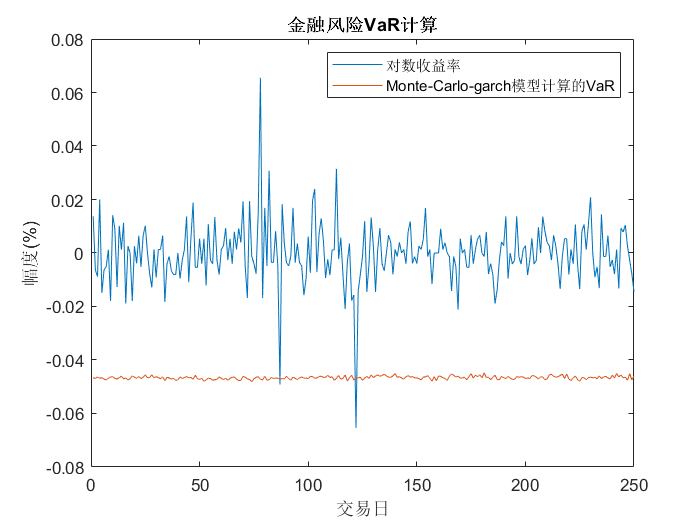

plot(rtn(n-k+1:end)); hold on;
plot(VaR);
hold off
legend({'对数收益率', 'Monte-Carlo-garch模型计算的VaR'});
ylabel('幅度(%)');
xlabel('交易日');
title('金融风险VaR计算');

计算超限次数.

exceed = sum(rtn(n-k+1:end) < VaR');
fprintf('超限次数: %d\n', exceed);

超限次数: 2
